defaultDir = 'M:\Bergles Lab Data\Papers\P2ry1'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd(['Figure 1 - Gq Pharm and P2ry1 Expression']);

%parameters for analysis
peakProminenceThr = 25; %threshold in pA
conditionTimes = [0 600];


%%dir 
dname = '.\Data\Han Chin\ISC*\*\*gfv.abf';
filenames = dir(dname);

conditions = {};
for i = 1:size(filenames,1)
    tempstr = filenames(i).folder;
    [tokens, matches] = regexp(tempstr,'\ISC (.*)\','tokens','match');
    conditions(i) = tokens{1};
end


if exist('cell') | exist('cellS') 
   clear 'cell' 'cellS'; 
end

for i = 1:size(filenames,1)
    
        [d,time,SR] = loadPclampData([filenames(i).folder '\' filenames(i).name]);
        d = d(:,1);
        out = msbackadj(time, -d, 'WindowSize', 60,'StepSize',30);
        out = lowpass(out,5,5000);
        %figure for assessing basleine
        % figure; plot(time,out);
%         hold on;
%         plot(time,d-out);
        [pks,locs] = findpeaks(out,time,'MinPeakProminence', peakProminenceThr);
        %uncomment for peaks graph
        %findpeaks(out,time,'MinPeakProminence', peakProminenceThr)
        cellS(i).rawLocPk = [locs pks];
        
        if exist('stats')
            clear 'stats'; 
        end
        
        cellS(i).condition = conditions{i};
        
        stats.numPeaks = size(pks,1);
        stats.meanAmp = mean(pks,1);
        cumFunc = cumtrapz(time,out);
        stats.integral = cumFunc(end);
        
      
        cellS(i).stats = stats;
        tempCell = cellS(i);
        [~,name, ext] = fileparts(filenames(i).name)
        save([filenames(i).folder '\' name '_stats.mat'],'tempCell','-mat');
end

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - Gq Pharm and P2ry1 Expression\Data\Han Chin\ISC BAPTA-AM\120516_Cell1\2012_05_16_0000_gfv.abf..
**** available channels:
    'IN 0'
    'IN 1'
    'IN 2'

data were acquired in gap-free mode
total length of recording: 600.0 s ~ 10 min
sampling interval: 99 µs
memory requirement for complete upload in matlab: 139 MB


name = '2012_05_16_0000_gfv'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - Gq Pharm and P2ry1 Expression\Data\Han Chin\ISC BAPTA-AM\120516_Cell2\2012_05_16_0002_gfv.abf..
**** available channels:
    'IN 0'
    'IN 1'
    'IN 2'

data were acquired in gap-free mode
total length of recording: 567.4 s ~ 9 min
sampling interval: 99 µs
memory requirement for complete upload in matlab: 131 MB


name = '2012_05_16_0002_gfv'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - Gq Pharm and P2ry1 Expression\Data\Han Chin\ISC BAPTA-AM\120516_Cell3\2012_05_16_0006_gfv.abf..
**** available channels:
    'IN 0'
    'IN 1'
    'IN 2'

data were acquired in gap-free mode
total length of recording: 600.0 s ~ 10 min
sampling interval: 99 µs
memory requirement for complete upload in matlab: 139 MB


name = '2012_05_16_0006_gfv'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - Gq Pharm and P2ry1 Expression\Data\Han Chin\ISC BAPTA-AM\120516_Cell4\2012_05_16_0008_gfv.abf..
**** available channels:
    'IN 0'
    'IN 1'
    'IN 2'

data were acquired in gap-free mode
total length of recording: 600.0 s ~ 10 min
sampling interval: 99 µs
memory requirement for complete upload in matlab: 139 MB


name = '2012_05_16_0008_gfv'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - Gq Pharm and P2ry1 Expression\Data\Han Chin\ISC BAPTA-AM\120517_Cell1\2012_05_17_0000_gfv.abf..
**** available channels:
    'IN 0'
    'IN 1'
    'IN 2'

data were acquired in gap-free mode
total length of recording: 600.0 s ~ 10 min
sampling interval: 99 µs
memory requirement for complete upload in matlab: 139 MB


name = '2012_05_17_0000_gfv'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - Gq Pharm and P2ry1 Expression\Data\Han Chin\ISC BAPTA-AM\120517_Cell2\2012_05_17_0002_gfv.abf..
**** available channels:
    'IN 0'
    'IN 1'
    'IN 2'

data were acquired in gap-free mode
total length of recording: 600.0 s ~ 10 min
sampling interval: 99 µs
memory requirement for complete upload in matlab: 139 MB


name = '2012_05_17_0002_gfv'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - Gq Pharm and P2ry1 Expression\Data\Han Chin\ISC BAPTA-AM\120517_Cell3\2012_05_17_0004_gfv.abf..
**** available channels:
    'IN 0'
    'IN 1'
    'IN 2'

data were acquired in gap-free mode
total length of recording: 600.0 s ~ 10 min
sampling interval: 99 µs
memory requirement for complete upload in matlab: 139 MB


name = '2012_05_17_0004_gfv'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - Gq Pharm and P2ry1 Expression\Data\Han Chin\ISC BAPTA-AM\120517_Cell4\2012_05_17_0006_gfv.abf..
**** available channels:
    'IN 0'
    'IN 1'
    'IN 2'

data were acquired in gap-free mode
total length of recording: 600.0 s ~ 10 min
sampling interval: 99 µs
memory requirement for complete upload in matlab: 139 MB


name = '2012_05_17_0006_gfv'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - Gq Pharm and P2ry1 Expression\Data\Han Chin\ISC BAPTA-AM\120522_Cell1\2012_05_22_0000_gfv.abf..
**** available channels:
    'IN 0'
    'IN 1'
    'IN 2'

data were acquired in gap-free mode
total length of recording: 600.0 s ~ 10 min
sampling interval: 99 µs
memory requirement for complete upload in matlab: 139 MB


name = '2012_05_22_0000_gfv'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - Gq Pharm and P2ry1 Expression\Data\Han Chin\ISC BAPTA-AM\120522_Cell10\2012_05_22_0020_gfv.abf..
**** available channels:
    'IN 0'
    'IN 1'
    'IN 2'

data were acquired in gap-free mode
total length of recording: 600.0 s ~ 10 min
sampling interval: 99 µs
memory requirement for complete upload in matlab: 139 MB


name = '2012_05_22_0020_gfv'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - Gq Pharm and P2ry1 Expression\Data\Han Chin\ISC BAPTA-AM\120522_Cell2\2012_05_22_0002_gfv.abf..
**** available channels:
    'IN 0'
    'IN 1'
    'IN 2'

data were acquired in gap-free mode
total length of recording: 600.0 s ~ 10 min
sampling interval: 99 µs
memory requirement for complete upload in matlab: 139 MB


name = '2012_05_22_0002_gfv'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - Gq Pharm and P2ry1 Expression\Data\Han Chin\ISC BAPTA-AM\120522_Cell3\2012_05_22_0004_gfv.abf..
**** available channels:
    'IN 0'
    'IN 1'
    'IN 2'

data were acquired in gap-free mode
total length of recording: 600.0 s ~ 10 min
sampling interval: 99 µs
memory requirement for complete upload in matlab: 139 MB


name = '2012_05_22_0004_gfv'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - Gq Pharm and P2ry1 Expression\Data\Han Chin\ISC BAPTA-AM\120522_Cell4\2012_05_22_0006_gfv.abf..
**** available channels:
    'IN 0'
    'IN 1'
    'IN 2'

data were acquired in gap-free mode
total length of recording: 600.0 s ~ 10 min
sampling interval: 99 µs
memory requirement for complete upload in matlab: 139 MB


name = '2012_05_22_0006_gfv'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - Gq Pharm and P2ry1 Expression\Data\Han Chin\ISC BAPTA-AM\120522_Cell9\2012_05_22_0017_gfv.abf..
**** available channels:
    'IN 0'
    'IN 1'
    'IN 2'

data were acquired in gap-free mode
total length of recording: 600.0 s ~ 10 min
sampling interval: 99 µs
memory requirement for complete upload in matlab: 139 MB


name = '2012_05_22_0017_gfv'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - Gq Pharm and P2ry1 Expression\Data\Han Chin\ISC BAPTA-AM\120525_Cell1\2012_05_25_0000_gfv.abf..
**** available channels:
    'IN 0'
    'IN 1'
    'IN 2'

data were acquired in gap-free mode
total length of recording: 600.0 s ~ 10 min
sampling interval: 99 µs
memory requirement for complete upload in matlab: 139 MB


name = '2012_05_25_0000_gfv'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - Gq Pharm and P2ry1 Expression\Data\Han Chin\ISC BAPTA-AM\120525_Cell2\2012_05_25_0002_gfv.abf..
**** available channels:
    'IN 0'
    'IN 1'
    'IN 2'

data were acquired in gap-free mode
total length of recording: 600.0 s ~ 10 min
sampling interval: 99 µs
memory requirement for complete upload in matlab: 139 MB


condNum =  unique({cellS.condition})

condNum = 1×5 cell array
    {'BAPTA-AM'}    {'DMSO Control'}    {'Thapsigargin'}    {'U73122'}    {'U73343'}


for i = 1:size(condNum,2)
    index = find(contains({cellS.condition},condNum{i}))
    tempPks = []; tempMeans = []; tempInts = [];
    for j = 1:size(index,2)
        tempPks(j)= cellS(index(j)).stats.numPeaks;
        tempMeans(j) = cellS(index(j)).stats.meanAmp;
        tempInts(j) = cellS(index(j)).stats.integral;
    end
    peaks{i} = tempPks;
    means{i} = tempMeans;
    ints{i} = tempInts;
end

index =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17


index =     18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33


index =     34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53


index =     54    55    56    57    58    59    60    61    62    63    64    65    66    67


index =     68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83


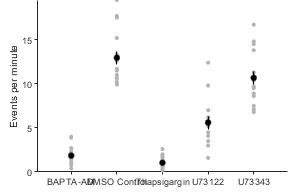

c =     1.0000    2.0000  -13.2626  -11.0974   -8.9322    0.0000
    1.0000    3.0000   -1.2468    0.8038    2.8544    0.8088
    1.0000    4.0000   -5.9918   -3.7483   -1.5049    0.0001
    1.0000    5.0000  -10.9814   -8.8162   -6.6510    0.0000
    2.0000    3.0000    9.8163   11.9013   13.9862    0.0000
    2.0000    4.0000    5.0742    7.3491    9.6240    0.0000
    2.0000    5.0000    0.0835    2.2813    4.4790    0.0380
    3.0000    4.0000   -6.7183   -4.5521   -2.3860    0.0000
    3.0000    5.0000  -11.7050   -9.6200   -7.5350    0.0000
    4.0000    5.0000   -7.3427   -5.0679   -2.7930    0.0000


compare5(peaks{1}/10, peaks{2}/10,peaks{3}/10, peaks{4}/10, peaks{5}/10, condNum, 'Events per minute', [3 2]);

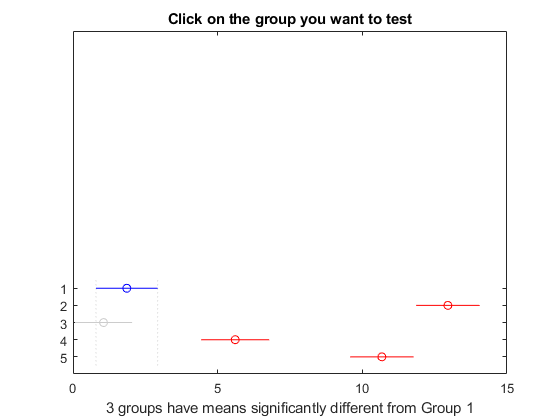

ylim([0 20]);

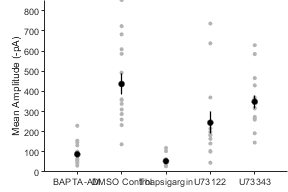

c =     1.0000    2.0000 -481.1189 -348.4755 -215.8322    0.0000
    1.0000    3.0000  -91.6462   33.9782  159.6027    0.9424
    1.0000    4.0000 -294.3613 -156.9238  -19.4863    0.0171
    1.0000    5.0000 -393.4953 -260.8520 -128.2087    0.0000
    2.0000    3.0000  254.7249  382.4538  510.1827    0.0000
    2.0000    4.0000   52.1881  191.5517  330.9154    0.0023
    2.0000    5.0000  -47.0145   87.6235  222.2616    0.3711
    3.0000    4.0000 -323.6028 -190.9020  -58.2013    0.0012
    3.0000    5.0000 -422.5591 -294.8303 -167.1014    0.0000
    4.0000    5.0000 -243.2918 -103.9282   35.4354    0.2380


compare5(means{1}, means{2},means{3}, means{4}, means{5}, condNum, 'Mean Amplitude (-pA)', [3 2]);

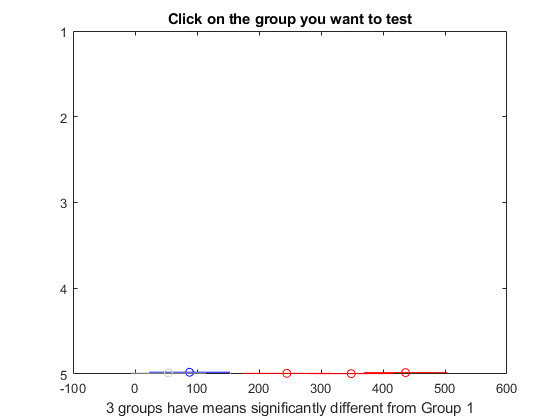

ylim([0 1000]);
yticks([0:250:1000]);

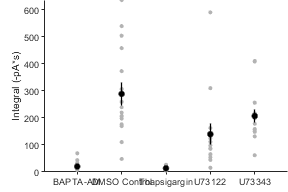

c =     1.0000    2.0000 -368.5974 -268.0791 -167.5608    0.0000
    1.0000    3.0000  -88.6197    6.5796  101.7790    0.9997
    1.0000    4.0000 -223.3814 -119.2301  -15.0787    0.0167
    1.0000    5.0000 -287.0950 -186.5767  -86.0585    0.0000
    2.0000    3.0000  177.8647  274.6588  371.4528    0.0000
    2.0000    4.0000   43.2381  148.8491  254.4601    0.0016
    2.0000    5.0000  -20.5275   81.5024  183.5323    0.1794
    3.0000    4.0000 -226.3715 -125.8097  -25.2479    0.0069
    3.0000    5.0000 -289.9504 -193.1564  -96.3623    0.0000
    4.0000    5.0000 -172.9577  -67.3467   38.2643    0.3920


compare5(ints{1}/600, ints{2}/600,ints{3}/600, ints{4}/600,ints{5}/600, condNum, 'Integral (-pA*s)', [3 2]);

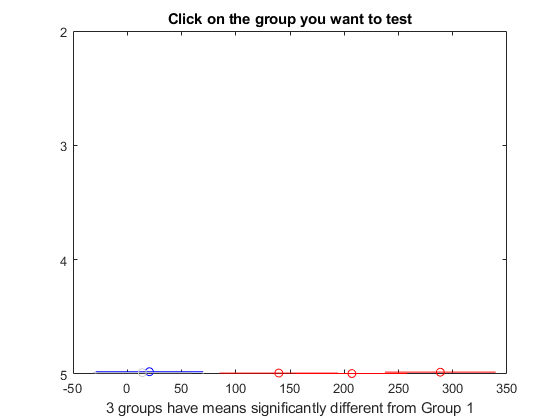

ylim([0 750]);
yticks([0:250:750]);

%parameters for analysis
pulse = -100; %test pulse in pA for resistance measurement
pulseTime = [0 0.01 0.2 0.26]; %periods to measure resistance [baseline_start baseline_end ss_start ss_end]
peakProminenceThr = 25; %threshold in pA
conditionTimes = [0 300];

%%dir 
dname = '.\Data\KO_MRS_PPADS_PT';
temp = dir(dname);
folderlist = temp(3:end);
dname = '.\Data\KO_PT';
temp = dir(dname);
folderlist = [folderlist; temp(3:end)];
dname = '.\Data\KO_BBE_PT';
temp = dir(dname);
folderlist = [folderlist; temp(3:end)];

analyze = [1 1 1 0];

if exist('cell') | exist('cellS') 
   clear 'cell' 'cellS'; 
end

for i = 1:size(folderlist,1)
    if analyze(1)
        fileList = loadFileList([folderlist(i).folder '\' folderlist(i).name '\*_p.abf']);
        [d,time] = loadPclampData(fileList{1});
        cellS(i).bl_R = calcRm(d,time,pulse,pulseTime);
    end
    
    if analyze(2)
        fileList = loadFileList([folderlist(i).folder '\' folderlist(i).name '\*_gfi.abf']);
        [d,time,SR] = loadPclampData(fileList{1});
        out = msbackadj(time, d, 'WindowSize', 60,'StepSize',60);
        cellS(i).Vm = mean(d - out);
        %%figure for assessing basleine
        % figure; plot(time,d);
        %hold on; plot(time,out);
       % plot(time,d-out);
    end
    
    if analyze(3) %change in inward current
        fileList = loadFileList([folderlist(i).folder  '\' folderlist(i).name '\*_gfv.abf']);
        [d,time,SR] = loadPclampData(fileList{1});
        out = msbackadj(time, -d, 'WindowSize', 60,'StepSize',30);
        out = lowpass(out,5,5000);
        %figure for assessing basleine
        % figure; plot(time,out);
%         hold on;
%         plot(time,d-out);
        [pks,locs] = findpeaks(out,time,'MinPeakProminence', peakProminenceThr);
        %uncomment for peaks graph
        %findpeaks(out,time,'MinPeakProminence', peakProminenceThr)
        cellS(i).rawLocPk = [locs pks];
        
        if exist('stats')
            clear 'stats'; 
        end
        for j = 1:size(conditionTimes,1)
            stats(j).condition = conditions{j};
            stats(j).numPeaks = size(pks(locs > conditionTimes(j,1) & locs < conditionTimes(j,2)),1);
            stats(j).meanAmp = mean(pks(locs > conditionTimes(j,1) & locs < conditionTimes(j,2)),1);
            cumFunc = cumtrapz(time(time > conditionTimes(j,1) & time < conditionTimes(j,2)), ... 
                                     out(time > conditionTimes(j,1) & time < conditionTimes(j,2)));
            stats(j).integral = cumFunc(end);
            
        end
        
        cellS(i).stats = stats;

    end
   
    if analyze(4)
        fileList = loadFileList([folderlist(i).folder '\' folderlist(i).name '\*_pp.abf']);
        if ~isempty(fileList)
            [d,time] = loadPclampData(fileList{1});
            cellS(i).post_R = calcRm(d,time,pulse,pulseTime);
        end
    end
    
    
end

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_MRS_PPADS_PT\180823_Cell2\18823008_p.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_MRS_PPADS_PT\180823_Cell2\18823009_gfi.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 320.3 s ~ 5 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 12 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_MRS_PPADS_PT\180823_Cell2\18823011_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1528.8 s ~ 25 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 58 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_MRS_PPADS_PT\180823_Cell4\18823020_p.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_MRS_PPADS_PT\180823_Cell4\18823021_gfi.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 301.6 s ~ 5 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 12 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_MRS_PPADS_PT\180823_Cell4\18823025_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1505.5 s ~ 25 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 57 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_MRS_PPADS_PT\180827_Cell2\18827015_p.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_MRS_PPADS_PT\180827_Cell2\18827016_gfi.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 300.7 s ~ 5 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 11 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_MRS_PPADS_PT\180827_Cell2\18827018_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1501.1 s ~ 25 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 57 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180823_Cell1\18823000_p.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180823_Cell1\18823001_gfi.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 180.8 s ~ 3 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 7 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180823_Cell1\18823005_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 301.7 s ~ 5 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 12 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180823_Cell3\18823016_p.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180823_Cell3\18823017_gfi.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 187.0 s ~ 3 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 7 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180823_Cell3\18823018_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 301.3 s ~ 5 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 11 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180824_Cell1\18824000_p.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180824_Cell1\18824001_gfi.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 255.0 s ~ 4 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 10 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180824_Cell1\18824004_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 304.8 s ~ 5 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 12 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180824_Cell3\18824013_p.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180824_Cell3\18824014_gfi.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 300.4 s ~ 5 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 11 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180824_Cell3\18824016_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 426.3 s ~ 7 min
sampling interval: 50 µs
memory requirement for complete upload in matlab: 65 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180827_Cell1\18827000_p.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180827_Cell1\18827001_gfi.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 301.3 s ~ 5 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 11 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180827_Cell1\18827003_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 392.1 s ~ 7 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 15 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180827_Cell3\18827020_p.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180827_Cell3\18827021_gfi.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 330.9 s ~ 6 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 13 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180827_Cell3\18827022_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 739.1 s ~ 12 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 28 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180827_Cell4\18827026_p.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180827_Cell4\18827027_gfi.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 300.9 s ~ 5 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 11 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180827_Cell4\18827029_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 889.1 s ~ 15 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 34 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_BBE_PT\180824_Cell2_Uncoupled\18824009_p.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_BBE_PT\180824_Cell2_Uncoupled\18824010_gfi.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 384.6 s ~ 6 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 15 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_BBE_PT\180824_Cell2_Uncoupled\18824012_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 953.8 s ~ 16 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 36 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_BBE_PT\180824_Cell4_Uncoupled\18824020_p.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_BBE_PT\180824_Cell4_Uncoupled\18824021_gfi.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 325.4 s ~ 5 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 12 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_BBE_PT\180824_Cell4_Uncoupled\18824023_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 900.6 s ~ 15 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 34 MB




for i = 1:size(cellS,2)
    KOpkstatBlock(i,:) = [cellS(i).stats.numPeaks]/5;
    KOampstatBlock(i,:) = [cellS(i).stats.meanAmp];
    KOintstatBlock(i,:) = [cellS(i).stats.integral]/300;
    KOrinstatBlock(i,:) = cellS(i).bl_R;
    KOvmstatBlock(i,:) = cellS(i).Vm;
end

compare2C(pkstatBlock,KOpkstatBlock,conditions,'Events Per Minute',[3 2]);

    0.8232



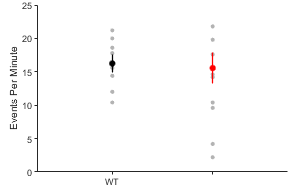

ylim([0 25]);
yticks(0:5:25);


compare2C(ampstatBlock,KOampstatBlock,conditions,'Mean Amp (pA)',[3 2]);

   1.8369e-05



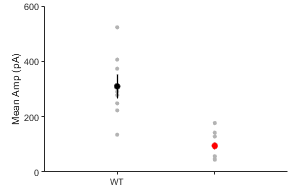

ylim([0 600]);
yticks(0:200:600);


compare2C(intstatBlock,KOintstatBlock,conditions,'Charge Transfer (-pA*s)',[3 2]);

   1.6415e-04



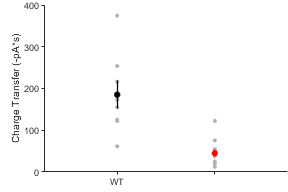

ylim([0 400]);
yticks(0:100:400);


compare2C(rinstatBlock,KOrinstatBlock,conditions,'Input Resistance (MOhm)',[3 2]);

    0.8580



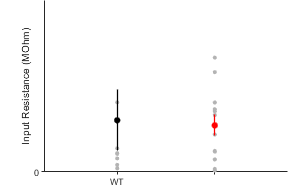

ylim([0 75]);
yticks(0:100:400);


compare2C(vmstatBlock,KOvmstatBlock,conditions,'Vm',[3 2]);

    0.2844



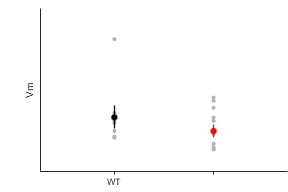

ylim([-100 -75]);
yticks(0:100:400);

% [p,~,stats] = anova1(pkstatBlock);
% [c] = multcompare(stats,'display','off')
% 
% [p,~,stats] = anova1(ampstatBlock);
% [c1] = multcompare(stats,'display','off')
% 
% [p,~,stats] = anova1(intstatBlock);
% [c2] = multcompare(stats,'display','off')